# Muscle frequency by localmax

% Choose Folder to process

    dirin = uigetdir(title="Select Folder to Process");
    filelist = dir(fullfile(dirin, "*.csv"));

    allHistosum = []; % One Histosum row per csv file (ie individual image)
    allBins = []; % One bins row per csv file

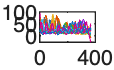

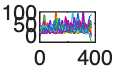

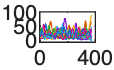

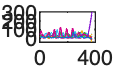

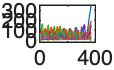

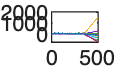

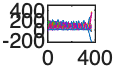

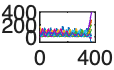


for f = 1:length(filelist)
    filein = fullfile(filelist(f).folder, filelist(f).name);

    T = readtable(filein, 'VariableNamingRule',"preserve");

    tablecol = size(T, 2);

    linein = [];

    j = 1;
    for i = 1:2:tablecol
        linein{j,1} = table2array(T(:,i));
        linein{j,2} = table2array(T(:,i + 1));
        
        linein{j,3} = sum(~isnan(linein{j,2})); % size of measured line in pixels
        j = j +1;
    end
    
    deltax = table2array(T(2,1))-table2array(T(1,1));
    d1 = table2array(T(2,1));
    d2 = table2array(T(1,1));
    linesizes = [];
    for i = 1:size(linein, 1)
        linesizes(i,1) = linein{i,3}.*deltax; % line size in microns
    end

    % *************
    % Smooth the lines
    % *************
    smdata20 = [];
    % smgreen100 = [];
    
    for i = 1:size(linein, 1);
        smdata20{i,1} = smooth(linein{i,2}, 20);
    % smgreen100(:,i) = smooth(wtgreen(:,i), 100);
    end
    
    % smgreen = smdata20 - smgreen100;

    figure();
    for i = 1:size(linein,1);
        plot(smdata20{i,1});
    hold on
    end
    hold off

    % *************
    % Get maxima points
    % *************
    fluormax = [];
    
    for i = 1:size(linein, 1);
        fluormax{i,1} = islocalmax(smdata20{i,1}, 1);
    end
    
    % greenmax = islocalmax(wtgreen, 1);

    maxlocs = [];
    maxdists = [];
    
    bins = (1:1:80) * 0.05; % deltax; 
    disthisto = [];
    
    for i = 1:size(fluormax, 1)
        maxlocs{i,1} = linein{i,1}(fluormax{i,1});
        maxdists{i,1} = diff(maxlocs{i,1});
        disthisto(:,i) = histcounts(maxdists{i,1}, bins);
    end

    % *************
    % Scale histogram counts by length of line they originate from
    % *************
    disthistoscaled = [];
    
    for i = 1:size(linesizes, 1)
        disthistoscaled(:,i) = disthisto(:,i)/linesizes(i,1); %normalize to length of line drawn
    end
    
    histosum = sum(disthistoscaled, 2)./size(linesizes,1); %normalize to number of lines drawn


    figure();
    plot(bins(1:end-1), histosum)
    xlabel("Distance between Peaks (micron)")
    ylabel("Fraction of peaks/micron")
    ylim([0 .12])
    xlim([0 4])
   

## Fraction Sarcomeric

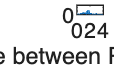

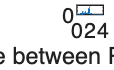

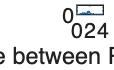

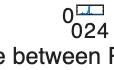

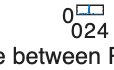

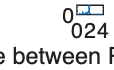

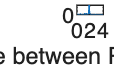

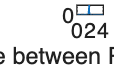

  % Sarcomeric region for mMac and Actinin (Whole Sarc only), bins= 1.55 to
  % 2.15
  % microns (bins 29 to 43). 
  
  sarcregion = zeros(size(bins, 2)-1, 1);
  sarcregion([29:43],1) = 1;
  sarcregion = logical(sarcregion);
  meansarcregion = mean(histosum(sarcregion));
  meannotsarc = mean(histosum(~sarcregion));
  
  sarcfraction = sum(histosum(sarcregion))/sum(histosum); %sum of the sarcomeric region as a fraction of total;
  

   save([filein(1:end-4), '.mat'], 'bins', 'histosum', 'disthistoscaled','meansarcregion','meannotsarc', 'sarcfraction', '-mat')

end 

## SarcFraction Binning

    %Version 3, based on SarcBin code by Joy-El Talbot, updated by Jared Talbot, Josh Kelley, Emily Tomak.
    % *** Run this on the .mat outputs from freq_bypeak*.mlx script. ***
 
    filelist = dir(fullfile(dirin, "*.mat"));
   
    % Define and create output folder

    filename = datestr(datetime("today"), "yyyy-mmm-dd");
    filename = strcat(filename, "_SarcFraction");

    processedFiles = []; % to store for future reproducibility

    % pre-define storage space needed 

    MeanSarcomeric = nan(length(filelist), 1);
    NonSarcomericMean = nan(length(filelist), 1);
    SarcomericFraction = nan(length(filelist), 1);

   for f = 1:length(filelist)
      
       load(fullfile(filelist(f).folder, filelist(f).name));

        MeanSarcomeric(f) = meansarcregion
        NonSarcomericMean (f) = meannotsarc
        SarcomericFraction (f) = sarcfraction

      processedFiles = [processedFiles; convertCharsToStrings(filelist(f).name)]; % store processed filenames

   end

MeanSarcomeric =     0.0184
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
       NaN
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
       NaN
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
       NaN
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
    0.0281
       NaN
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
    0.0011
       NaN
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
    0.8610
       NaN
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
    0.0281
    0.0288
       NaN
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
    0.0011
    0.0003
       NaN
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
    0.8610
    0.9523
       NaN
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
    0.0281
    0.0288
    0.0294
       NaN
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
    0.0011
    0.0003
    0.0005
       NaN
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
    0.8610
    0.9523
    0.9267
       NaN
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
    0.0281
    0.0288
    0.0294
    0.0275
       NaN


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
    0.0011
    0.0003
    0.0005
    0.0010
       NaN


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
    0.8610
    0.9523
    0.9267
    0.8640
       NaN


MeanSarcomeric =     0.0184
    0.0223
    0.0215
    0.0246
    0.0261
    0.0224
    0.0281
    0.0288
    0.0294
    0.0275
    0.0302


NonSarcomericMean =     0.0049
    0.0036
    0.0037
    0.0029
    0.0016
    0.0035
    0.0011
    0.0003
    0.0005
    0.0010
    0.0001


SarcomericFraction =     0.4702
    0.5905
    0.5768
    0.6670
    0.7960
    0.5972
    0.8610
    0.9523
    0.9267
    0.8640
    0.9909



    % build final table for export...

    results = table(processedFiles, MeanSarcomeric, NonSarcomericMean, SarcomericFraction);

    % CSV export of results table

    writetable(results, fullfile(dirin, strcat(filename, ".csv")));
